# Testing

## Testing di Robustezza

### Testing sul numero di input

load mathwork200.mat;
[R, OUT, IN] = PageRank();

Error using PageRank (line 5)
Inserire come parametro di input la matrice G

### Testing sul numero di output

load mathwork200.mat;
R = PageRank(G);

Error using PageRank (line 8)
Inserire come parametri di output R, OUT, IN

### Testing sulla matrice G

#### Testo se è una matrice

G=rand(10,10,10);
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 12)
Il primo input deve essere una matrice.

#### Testo se è sparsa o vuota

G=rand(100,100);
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 14)
La matrice deve essere sparsa e non vuota.

G=[];
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 14)
La matrice deve essere sparsa e non vuota.

#### Testo se è quadrata

G=sparse(rand(100,50));
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 16)
La matrice deve essere quadrata.

#### Testo se è almeno di dimensione 2

G=sparse(rand(1,1));
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 18)
La matrice deve essere almeno 2x2

#### Testo se è composta da elementi logical

G=sparse(rand(100,100));
[R, OUT, IN] = PageRank(G);

Error using PageRank (line 18)
Gli elementi della matrice devono essere logici.

## Testing di Funzionamento

load mathwork200.mat;
[R, OUT, IN] = PageRank(G)

R =    0.001526677743954
   0.004952923751719
   0.004291151787463
   0.004291151787463
   0.004291151787463
   0.004291151787463
   0.004291151787463
   0.004291151787463
   0.004291151787463
   0.004291151787463


OUT =    (1,1)       20
   (2,1)       20
   (3,1)       20
   (4,1)       21
   (5,1)       21
   (6,1)       20
   (7,1)       20
   (8,1)       20
   (9,1)       20
  (10,1)       20
  (11,1)       20
  (12,1)       20
  (13,1)       20
  (14,1)       20
  (15,1)       20
  (16,1)        3
  (21,1)       19
  (22,1)       19
  (23,1)       19
  (25,1)       20
  (26,1)       13
  (29,1)       19
  (30,1)       19
  (31,1)       19
  (32,1)       19
  (33,1)       19
  (34,1)       19
  (35,1)       19
  (36,1)       19
  (37,1)       19
  (38,1)       19
  (41,1)      123
  (45,1)       12
  (46,1)        1
  (47,1)       12
  (48,1)       12
  (49,1)       13
  (50,1)       13
  (51,1)       12
  (52,1)       12
  (53,1)       13
  (54,1)        1
  (55,1)       13
  (56,1)        1
  (60,1)       21
  (64,1)        5
  (65,1)       19
  (66,1)        4
  (67,1)        4
  (68,1)        4
  (69,1)        4
  (70,1)       21
  (82,1)       21
  (85,1)       15
  (86,1)       14
  (8

IN =    (2,1)       19
   (3,1)       17
   (4,1)       17
   (5,1)       17
   (6,1)       17
   (7,1)       17
   (8,1)       17
   (9,1)       17
  (10,1)       17
  (11,1)       17
  (12,1)       17
  (13,1)       17
  (14,1)       17
  (15,1)       17
  (16,1)       91
  (17,1)       17
  (18,1)       36
  (19,1)       36
  (20,1)       46
  (21,1)        3
  (22,1)       11
  (23,1)        2
  (24,1)        2
  (25,1)        2
  (26,1)        5
  (27,1)       11
  (28,1)       10
  (29,1)       10
  (30,1)        2
  (31,1)        2
  (32,1)        2
  (33,1)        2
  (34,1)        2
  (35,1)        2
  (36,1)        2
  (37,1)        2
  (38,1)        2
  (39,1)        2
  (40,1)        4
  (41,1)       23
  (42,1)        1
  (43,1)       15
  (44,1)       15
  (45,1)       24
  (46,1)       16
  (47,1)       24
  (48,1)       24
  (49,1)       15
  (50,1)       24
  (51,1)       24
  (52,1)       24
  (53,1)       24
  (54,1)       17
  (55,1)       24
  (56,1)       17
  (57

load repubblica.mat;
[R, OUT, IN] = PageRank(G)

R =    0.003310330436957
   0.009119322719054
   0.009884764682581
   0.012046067683317
   0.009978193592158
   0.010442059932598
   0.019281967796491
   0.010442059932598
   0.010442059932598
   0.078575023400042


OUT =    (1,1)       99
  (10,1)       99
  (13,1)        1
  (15,1)        6
  (16,1)        6
  (22,1)       34
  (23,1)       32
  (24,1)       33
  (25,1)       32
  (26,1)       33
  (27,1)       32
  (28,1)       32
  (29,1)       32
  (30,1)       32
  (31,1)       33
  (32,1)        1
  (33,1)       16
  (35,1)       59
  (36,1)       16
  (37,1)       17
  (38,1)       11
  (39,1)        8
  (40,1)       23
  (41,1)       15
  (42,1)       55
  (43,1)       17
  (44,1)        4
  (45,1)       55
  (46,1)       55
  (47,1)       55
  (48,1)       30
  (49,1)        6
  (50,1)       22
  (51,1)       38
  (52,1)       25
  (53,1)       55
  (54,1)       55
  (55,1)       15
  (56,1)        4
  (57,1)       15
  (58,1)        8
  (59,1)       20
  (60,1)        5
  (61,1)        9
  (62,1)        8
  (63,1)        2
  (65,1)        2
  (66,1)        2
  (67,1)       38
  (69,1)       24
  (71,1)        4
  (72,1)        8
  (74,1)       44
  (75,1)       44
  (76,1)       59
  (7

IN =    (2,1)       34
   (3,1)       37
   (4,1)       40
   (5,1)       37
   (6,1)       38
   (7,1)       39
   (8,1)       38
   (9,1)       38
  (10,1)       71
  (11,1)       33
  (12,1)       13
  (13,1)       50
  (14,1)       34
  (15,1)       44
  (16,1)        3
  (17,1)       12
  (18,1)        4
  (19,1)        2
  (20,1)       47
  (21,1)        7
  (22,1)       13
  (23,1)       12
  (24,1)       12
  (25,1)       12
  (26,1)       13
  (27,1)       13
  (28,1)       13
  (29,1)       12
  (30,1)       13
  (31,1)       12
  (32,1)       41
  (33,1)       53
  (34,1)        2
  (35,1)       30
  (36,1)       31
  (37,1)       31
  (38,1)       30
  (39,1)       24
  (40,1)       27
  (41,1)       32
  (42,1)       26
  (43,1)       23
  (44,1)       60
  (45,1)       26
  (46,1)       29
  (47,1)       26
  (48,1)       26
  (49,1)       26
  (50,1)       27
  (51,1)       25
  (52,1)       30
  (53,1)       26
  (54,1)       26
  (55,1)       30
  (56,1)       27
  (57

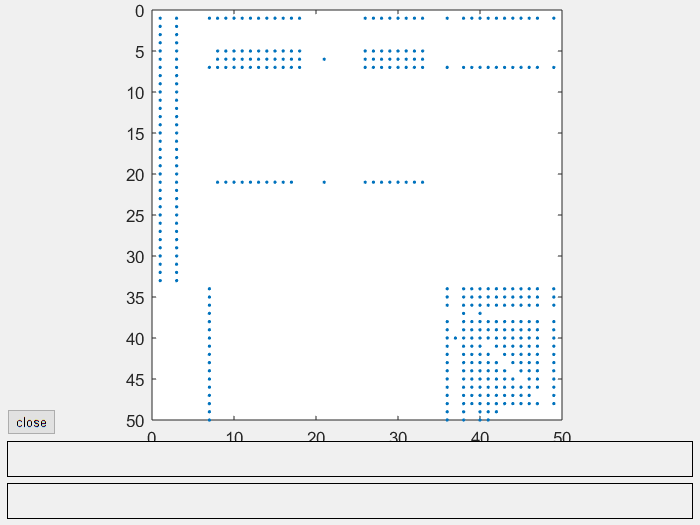

[U,G]=surfer('http://www.unina.it',50);

[R, OUT, IN] = PageRank(G)

R =    0.060476030042693
   0.009671544519183
   0.009671544519183
   0.009671544519183
   0.041321673989646
   0.070344717905559
   0.060476030042693
   0.009671544519183
   0.009671544519183
   0.009671544519183


OUT =    (1,1)       33
   (3,1)       33
   (7,1)       19
   (8,1)        5
   (9,1)        5
  (10,1)        5
  (11,1)        5
  (12,1)        5
  (13,1)        5
  (14,1)        5
  (15,1)        5
  (16,1)        5
  (17,1)        5
  (18,1)        4
  (21,1)        2
  (26,1)        5
  (27,1)        5
  (28,1)        5
  (29,1)        5
  (30,1)        5
  (31,1)        5
  (32,1)        5
  (33,1)        5
  (36,1)       18
  (37,1)        1
  (38,1)       19
  (39,1)       16
  (40,1)       19
  (41,1)       17
  (42,1)       16
  (43,1)       15
  (44,1)       15
  (45,1)       15
  (46,1)       16
  (47,1)       15
  (49,1)       16


IN =    (1,1)       34
   (2,1)        2
   (3,1)        2
   (4,1)        2
   (5,1)       21
   (6,1)       22
   (7,1)       34
   (8,1)        2
   (9,1)        2
  (10,1)        2
  (11,1)        2
  (12,1)        2
  (13,1)        2
  (14,1)        2
  (15,1)        2
  (16,1)        2
  (17,1)        2
  (18,1)        2
  (19,1)        2
  (20,1)        2
  (21,1)       21
  (22,1)        2
  (23,1)        2
  (24,1)        2
  (25,1)        2
  (26,1)        2
  (27,1)        2
  (28,1)        2
  (29,1)        2
  (30,1)        2
  (31,1)        2
  (32,1)        2
  (33,1)        2
  (34,1)       13
  (35,1)       13
  (36,1)       13
  (37,1)        3
  (38,1)       13
  (39,1)       13
  (40,1)       14
  (41,1)       12
  (42,1)       12
  (43,1)       12
  (44,1)       12
  (45,1)       12
  (46,1)       13
  (47,1)       12
  (48,1)       13
  (49,1)        6
  (50,1)        5


## Testing di Accuratezza

load mathwork200.mat;
H=digraph(G','omitselfloops');
[R, OUT, IN] = PageRank(G);
pg_ranks=centrality(H,'pagerank','MaxIterations',200,'FollowProbability',0.85,'Tolerance',10^-7);
err=norm(R-pg_ranks)/norm(pg_ranks)

err =      2.411817257931451e-06


load repubblica.mat;
H=digraph(G','omitselfloops');
[R, OUT, IN] = PageRank(G);
pg_ranks=centrality(H,'pagerank','MaxIterations',200,'FollowProbability',0.85,'Tolerance',10^-7);
err=norm(R-pg_ranks)/norm(pg_ranks)

err =      1.478002715325517e-07


[U,G]=surfer('http://www.unina.it',50);

H=digraph(G','omitselfloops');
[R, OUT, IN] = PageRank(G);
pg_ranks=centrality(H,'pagerank','MaxIterations',200,'FollowProbability',0.85,'Tolerance',10^-7);
err=norm(R-pg_ranks)/norm(pg_ranks)

err =      5.864905738502280e-07
